# Individual Assignment – Image Processing Fundamentals

## Option A: Comparison of Denoising Filters

**1. Objective**

The objective of this experiment is to compare three image denoising methods: median filtering, Gaussian filtering, and a combination of median and Gaussian filtering.

The experiment uses the MATLAB sample image `rice.png`. Gaussian noise and salt-and-pepper noise are added to the original image to simulate image degradation.

The filtered images will be compared using Peak Signal-to-Noise Ratio (PSNR), Structural Similarity Index (SSIM), and visual inspection of a zoomed image region.

**Research question:** Which of the three filtering methods provides the best balance between noise reduction and preservation of image details?

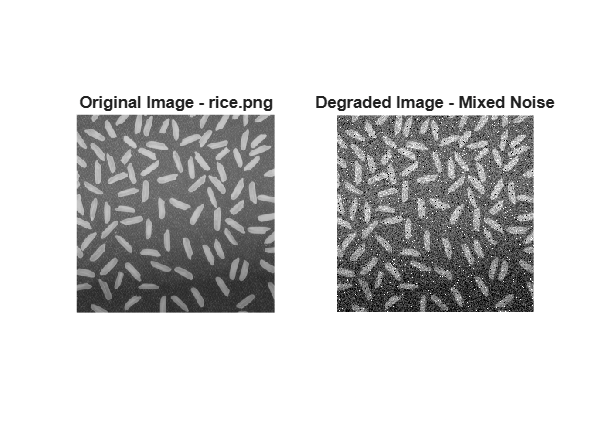


%% Step 1: Load and Degrade the Image

% Load the original reference image
Iref = imread('rice.png');

% Set the random seed for reproducibility
rng(42);

% Add Gaussian noise followed by salt-and-pepper noise
Id = imnoise(imnoise(Iref,'gaussian',0,0.01), ...
    'salt & pepper',0.02);

% Display the reference and degraded images
figure;

subplot(1,2,1);
imshow(Iref);
title('Original Image - rice.png');

subplot(1,2,2);
imshow(Id);
title('Degraded Image - Mixed Noise');


% Display image information
fprintf('Image size: %d x %d pixels\n', ...
    size(Iref,1), size(Iref,2));

Image size: 256 x 256 pixels



fprintf('Image data type: %s\n', class(Iref));

Image data type: uint8


**2. Image and Noise Description**

The reference image is `rice.png`, a grayscale sample image provided by MATLAB.

Two types of noise were applied to simulate image degradation:

- **Gaussian noise:** Added with a mean of 0 and a variance of 0.01.

- **Salt-and-pepper noise:** Applied with a density of 0.02, introducing randomly distributed black and white pixels.

The random seed was set to `rng(42)` to make the noise generation reproducible.

The same degraded image will be used for all three filtering methods to ensure a fair comparison.

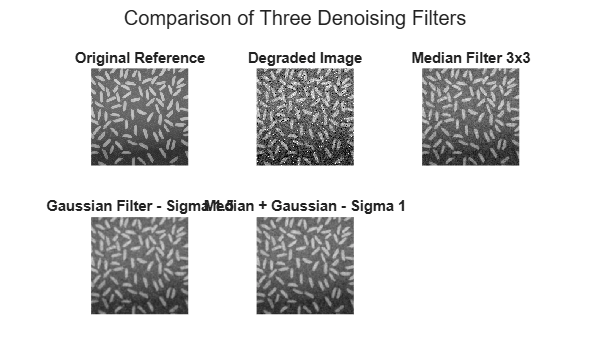


%% Step 2: Apply Three Denoising Filters

% Filter 1: 3x3 median filter
I_median = medfilt2(Id, [3 3]);

% Filter 2: Gaussian filter with sigma = 1.5
I_gaussian = imgaussfilt(Id, 1.5);

% Filter 3: Median 3x3 followed by Gaussian sigma = 1
I_combined = imgaussfilt(medfilt2(Id, [3 3]), 1);

% Display the original, degraded and filtered images
figure;
set(gcf, 'Position', [100 100 1100 650]);

subplot(2,3,1);
imshow(Iref);
title('Original Reference');

subplot(2,3,2);
imshow(Id);
title('Degraded Image');

subplot(2,3,3);
imshow(I_median);
title('Median Filter 3x3');

subplot(2,3,4);
imshow(I_gaussian);
title('Gaussian Filter - Sigma 1.5');

subplot(2,3,5);
imshow(I_combined);
title('Median + Gaussian - Sigma 1');

sgtitle('Comparison of Three Denoising Filters');

**3. Denoising Methods**

Three filtering methods were applied to the same degraded image.

**Median filtering:** A 3×3 median filter was used to reduce salt-and-pepper noise while preserving many image edges.

**Gaussian filtering:** A Gaussian filter with sigma 1.5 was applied to smooth image noise. However, Gaussian smoothing may also blur grain boundaries.

**Combined filtering:** A 3×3 median filter was applied first, followed by Gaussian smoothing with sigma 1. This method aims to remove impulse noise before reducing the remaining Gaussian noise.

The filter parameters were kept exactly as specified in the assignment to ensure a consistent comparison.


%% Step 3: Compare Image Quality Using PSNR and SSIM

% Calculate PSNR for the degraded image
psnr_degraded = psnr(Id, Iref);

% Calculate PSNR for the three filters
psnr_median = psnr(I_median, Iref);
psnr_gaussian = psnr(I_gaussian, Iref);
psnr_combined = psnr(I_combined, Iref);

% Calculate SSIM for the degraded image
ssim_degraded = ssim(Id, Iref);

% Calculate SSIM for the three filters
ssim_median = ssim(I_median, Iref);
ssim_gaussian = ssim(I_gaussian, Iref);
ssim_combined = ssim(I_combined, Iref);

% Create the results table
Method = {'Degraded Image'; ...
    'Median 3x3'; ...
    'Gaussian Sigma 1.5'; ...
    'Median + Gaussian Sigma 1'};

PSNR_dB = [psnr_degraded; ...
    psnr_median; ...
    psnr_gaussian; ...
    psnr_combined];

SSIM = [ssim_degraded; ...
    ssim_median; ...
    ssim_gaussian; ...
    ssim_combined];

Results = table(Method, PSNR_dB, SSIM);

% Display the comparison table
disp('PSNR and SSIM Comparison:');

PSNR and SSIM Comparison:


disp(Results);

               Method                PSNR_dB     SSIM  
    _____________________________    _______    _______

    {'Degraded Image'           }    18.088     0.36958
    {'Median 3x3'               }     25.37     0.62323
    {'Gaussian Sigma 1.5'       }    25.755     0.69213
    {'Median + Gaussian Sigma 1'}    26.368     0.70515




% Identify the best filter for each metric
filterNames = Method(2:4);

[bestPSNR, idxPSNR] = max(PSNR_dB(2:4));
[bestSSIM, idxSSIM] = max(SSIM(2:4));

fprintf('\nBest PSNR: %s (%.2f dB)\n', ...
    filterNames{idxPSNR}, bestPSNR);


Best PSNR: Median + Gaussian Sigma 1 (26.37 dB)



fprintf('Best SSIM: %s (%.4f)\n', ...
    filterNames{idxSSIM}, bestSSIM);

Best SSIM: Median + Gaussian Sigma 1 (0.7051)


**4. Quantitative Comparison**

The image quality was evaluated using PSNR and SSIM, with the original `rice.png` image as the reference.

PSNR measures pixel-level differences between the processed and reference images, while SSIM evaluates their structural similarity.

Higher PSNR and SSIM values generally indicate better reconstruction quality.

The degraded image was also included in the comparison to show how much each filter improved or changed the image relative to the noisy input.

The results will be considered together with a visual comparison of the grain boundaries and remaining noise.

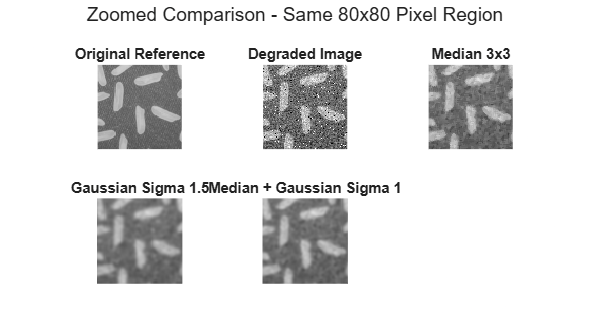


%% Step 4: Zoomed Image Comparison

% Select the same 80x80 pixel region for all images
rows = 70:149;
cols = 70:149;

% Extract the selected region
zoom_ref = Iref(rows, cols);
zoom_degraded = Id(rows, cols);
zoom_median = I_median(rows, cols);
zoom_gaussian = I_gaussian(rows, cols);
zoom_combined = I_combined(rows, cols);

% Display all five zoomed regions
figure;
set(gcf, 'Position', [100 100 1200 650]);

subplot(2,3,1);
imshow(zoom_ref);
title('Original Reference');

subplot(2,3,2);
imshow(zoom_degraded);
title('Degraded Image');

subplot(2,3,3);
imshow(zoom_median);
title('Median 3x3');

subplot(2,3,4);
imshow(zoom_gaussian);
title('Gaussian Sigma 1.5');

subplot(2,3,5);
imshow(zoom_combined);
title('Median + Gaussian Sigma 1');

sgtitle('Zoomed Comparison - Same 80x80 Pixel Region');

%% Step 5: Save Results

% Create the results folder if it does not exist
if ~exist('results', 'dir')
    mkdir('results');
end

% Save the three processed images
imwrite(I_median, 'results/median.png');
imwrite(I_gaussian, 'results/gaussian.png');
imwrite(I_combined, 'results/combined.png');

% Save the zoomed comparison figure
exportgraphics(gcf, 'results/zoomed_comparison.png', ...
    'Resolution', 300);


% Save the PSNR and SSIM table
writetable(Results, 'results/comparison_table.csv');

disp('Results saved successfully in the results folder.');

Results saved successfully in the results folder.


**5. Visual Comparison**

An 80 × 80-pixel region was selected from the same location in all five images to compare the effects of filtering.

The comparison focuses on remaining noise, the sharpness of rice grain boundaries, and the loss of fine details.

Median filtering is expected to reduce isolated salt-and-pepper noise, while Gaussian filtering smooths local intensity variations. The combined method applies both operations and may provide a useful balance, although it can also introduce additional blur.

The final preference will be based on the measured PSNR and SSIM values together with the visual appearance of the zoomed images.

## 6. Results and Discussion

**6.1 Quantitative Results**

The three denoising methods were evaluated using PSNR and SSIM, with the original `rice.png` image as the reference.

The degraded image had a PSNR of 18.088 dB and an SSIM of 0.36958, indicating a considerable difference from the original image.

After filtering, all three methods improved both measurements. The median filter achieved a PSNR of 25.370 dB and an SSIM of 0.62323. The Gaussian filter achieved 25.755 dB and 0.69213, respectively.

The combined median and Gaussian filter produced the highest results, with a PSNR of 26.368 dB and an SSIM of 0.70515.

These results indicate that the combined method provided the closest reconstruction to the reference image according to both measurements.

**6.2 Visual Comparison**

The same 80 × 80-pixel region was selected from the original, degraded, and filtered images to compare noise reduction and preservation of image details.

Median filtering is effective at reducing isolated salt-and-pepper noise, although some Gaussian noise may remain.

Gaussian filtering reduces intensity variations but can also smooth grain boundaries.

The combined method first applies median filtering to reduce impulse noise and then uses Gaussian smoothing to reduce remaining intensity variations.

Although the combined method achieved the best numerical measurements, some blurring of fine details may still occur because both filtering operations modify the image.

**6.3 Preferred Method**

For this experiment, I prefer the **combined median and Gaussian filter**.

It achieved the highest PSNR of 26.368 dB and the highest SSIM of 0.70515 among the three tested methods.

The combined method is suitable for this experiment because the degraded image contains both Gaussian and salt-and-pepper noise. Median filtering addresses impulse noise, while Gaussian filtering reduces remaining intensity variations.

Based on the numerical measurements, this method provides the best overall result among the three specified configurations.

**6.4 Limitations**

One limitation is that the experiment uses only one reference image and one fixed noise realization generated with `rng(42)`. The results may differ for other images or noise conditions.

Another limitation is that PSNR and SSIM do not fully represent perceived image quality. A filtered image may achieve high numerical measurements while losing important fine details.

Additionally, the filter parameters were fixed according to the assignment instructions. Therefore, the experiment identifies the best-performing method among the tested configurations rather than the best possible denoising method in general.

## 7. Conclusion

This experiment compared median filtering, Gaussian filtering, and combined median and Gaussian filtering for removing mixed noise from `rice.png`.

All three filters improved the image quality compared with the degraded image.

The combined median and Gaussian filter achieved the best results, with a PSNR of 26.368 dB and an SSIM of 0.70515.

Therefore, the combined filter was selected as the preferred method for this experiment. However, the results also demonstrate that noise reduction must be balanced against the possible loss of image details.